%Create datastores
blurDir = fullfile('.','nah','train_blur','train','train_blur');
sharpDir = fullfile('.','nah','train_sharp','train','train_sharp');

blurimds = imageDatastore(blurDir,"IncludeSubfolders",1);
trueimds = imageDatastore(sharpDir,"IncludeSubfolders",1);

imSize = [144 256];
trainBlur = augmentedImageDatastore(imSize,blurimds);
trainTrue = augmentedImageDatastore(imSize,trueimds);

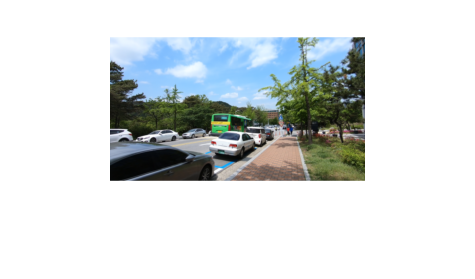

imBlurs = trainBlur.read();
imTrues = trainTrue.read();
blur = imBlurs(1,1);
true = imTrues(1,1);
figure;
imshow(blur.input{1})

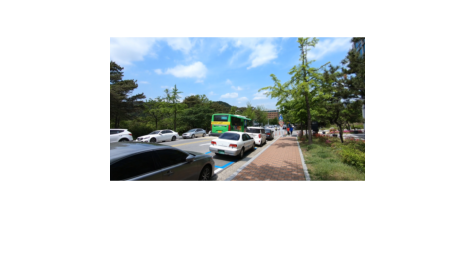

imshow(true.input{1})

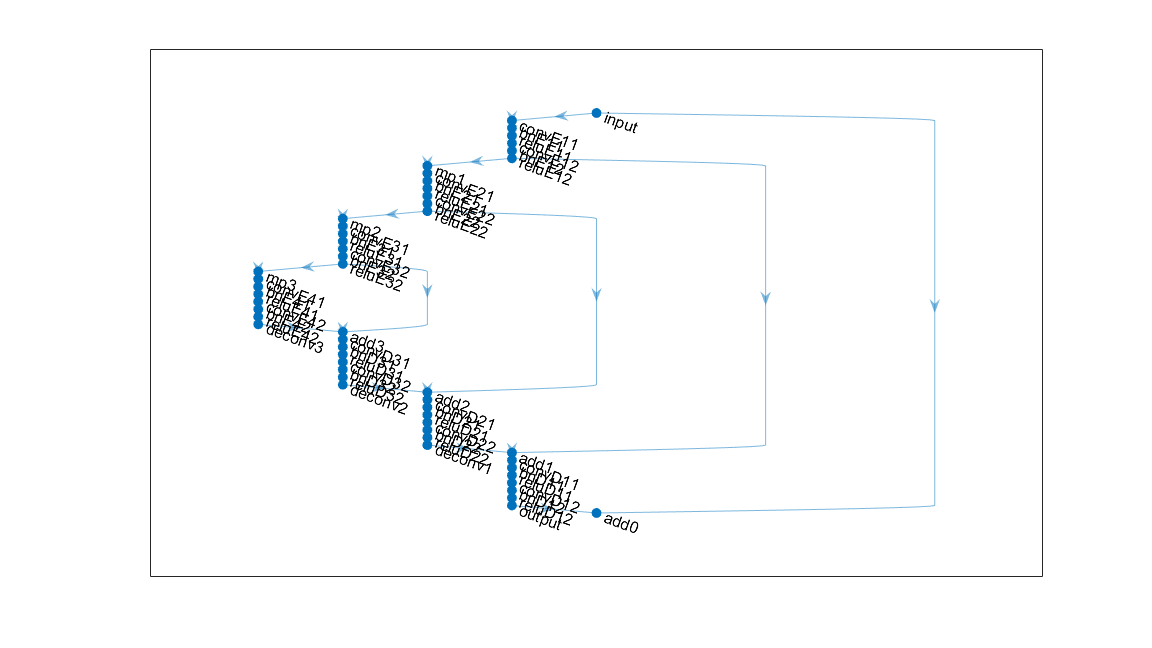

inputSize = [imSize(1) imSize(2) 3];
n_filters = 32;
layers = [imageInputLayer(inputSize,'Name','input','Normalization','None')
    
    convolution2dLayer(3,n_filters,'Name','convE11','Padding','same')
    batchNormalizationLayer('Name','bnE11')
    reluLayer('Name','reluE11')
    
    convolution2dLayer(3,n_filters,'Name','convE12','Padding','same')
    batchNormalizationLayer('Name','bnE12')
    reluLayer('Name','reluE12')
    
    maxPooling2dLayer(2,'Stride',2,'Name','mp1')
    
    convolution2dLayer(3, n_filters * 2,'Name','convE21','Padding','same')
    batchNormalizationLayer('Name','bnE21')
    reluLayer('Name','reluE21')
    
    convolution2dLayer(3, n_filters * 2,'Name','convE22','Padding','same')
    batchNormalizationLayer('Name','bnE22')
    reluLayer('Name','reluE22')
    
    maxPooling2dLayer(2,'Stride',2,'Name','mp2')
    
    convolution2dLayer(3, n_filters * 4,'Name','convE31','Padding','same')
    batchNormalizationLayer('Name','bnE31')
    reluLayer('Name','reluE31')
    
    convolution2dLayer(3, n_filters * 4,'Name','convE32','Padding','same')
    batchNormalizationLayer('Name','bnE32')
    reluLayer('Name','reluE32')
    
    maxPooling2dLayer(2,'Stride',2,'Name','mp3')
    
    convolution2dLayer(3, n_filters * 8,'Name','convE41','Padding','same')
    batchNormalizationLayer('Name','bnE41')
    reluLayer('Name','reluE41')
    
    convolution2dLayer(3, n_filters * 8,'Name','convE42','Padding','same')
    batchNormalizationLayer('Name','bnE42')
    reluLayer('Name','reluE42')
    
    transposedConv2dLayer(2, n_filters * 4,'Name','deconv3',"Stride",2)
    additionLayer(2,'Name','add3')
    
    convolution2dLayer(3, n_filters * 4,'Name','convD31','Padding','same')
    batchNormalizationLayer('Name','bnD31')
    reluLayer('Name','reluD31')
    
    convolution2dLayer(3, n_filters * 4,'Name','convD32','Padding','same')
    batchNormalizationLayer('Name','bnD32')
    reluLayer('Name','reluD32')
    
    transposedConv2dLayer(2, n_filters * 2,'Name','deconv2',"Stride",2)
    additionLayer(2,'Name','add2')
    
    convolution2dLayer(3, n_filters * 2,'Name','convD21','Padding','same')
    batchNormalizationLayer('Name','bnD21')
    reluLayer('Name','reluD21')
    
    convolution2dLayer(3, n_filters * 2,'Name','convD22','Padding','same')
    batchNormalizationLayer('Name','bnD22')
    reluLayer('Name','reluD22')
    
    transposedConv2dLayer(2, n_filters,'Name','deconv1',"Stride",2)
    additionLayer(2,'Name','add1')
    
    convolution2dLayer(3, n_filters,'Name','convD11','Padding','same')
    batchNormalizationLayer('Name','bnD11')
    reluLayer('Name','reluD11')
    
    convolution2dLayer(3, n_filters,'Name','convD12','Padding','same')
    batchNormalizationLayer('Name','bnD12')
    reluLayer('Name','reluD12')
    
    convolution2dLayer(1,3,"Padding",'same','Name','output')
    additionLayer(2,'Name','add0')];

lgraph = layerGraph(layers);
lgraph = lgraph.connectLayers('reluE22','add2/in2');
lgraph = lgraph.connectLayers('reluE32','add3/in2');
lgraph = lgraph.connectLayers('reluE12','add1/in2');
lgraph = lgraph.connectLayers('input','add0/in2');
dlnetGenerator = dlnetwork(lgraph);
figure('Units','normalized','Position',[0.2 0.2 0.6 0.6]);
plot(lgraph);

dropoutProb = 0.5;
numFilters = 32;
scale = 0.2;
filterSize = 5;

layersDiscriminator = [
    imageInputLayer(inputSize,'Normalization','none','Name','in')
    dropoutLayer(0.5,'Name','dropout')
    convolution2dLayer(filterSize,numFilters,'Stride',2,'Padding','same','Name','conv1')
    leakyReluLayer(scale,'Name','lrelu1')
    convolution2dLayer(filterSize,2*numFilters,'Stride',2,'Padding','same','Name','conv2')
    batchNormalizationLayer('Name','bn2')
    leakyReluLayer(scale,'Name','lrelu2')
    convolution2dLayer(filterSize,4*numFilters,'Stride',2,'Padding','same','Name','conv3')
    batchNormalizationLayer('Name','bn3')
    leakyReluLayer(scale,'Name','lrelu3')
    convolution2dLayer(filterSize,8*numFilters,'Stride',2,'Padding','same','Name','conv4')
    batchNormalizationLayer('Name','bn4')
    leakyReluLayer(scale,'Name','lrelu4')
    convolution2dLayer(filterSize,16*numFilters,'Stride',2,'Padding','same','Name','conv5')
    batchNormalizationLayer('Name','bn5')
    leakyReluLayer(scale,'Name','lrelu5')
    convolution2dLayer([5 8],1,'Name','conv6')];

lgraphDiscriminator = layerGraph(layersDiscriminator);
dlnetDiscriminator = dlnetwork(lgraphDiscriminator);

numEpochs = 1;
miniBatchSize = 16;
trainBlur.MiniBatchSize = miniBatchSize;
trainTrue.MiniBatchSize = miniBatchSize;
learnRate = 0.0002;
gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;
flipFactor = 0.05;
validationFrequency = 100;

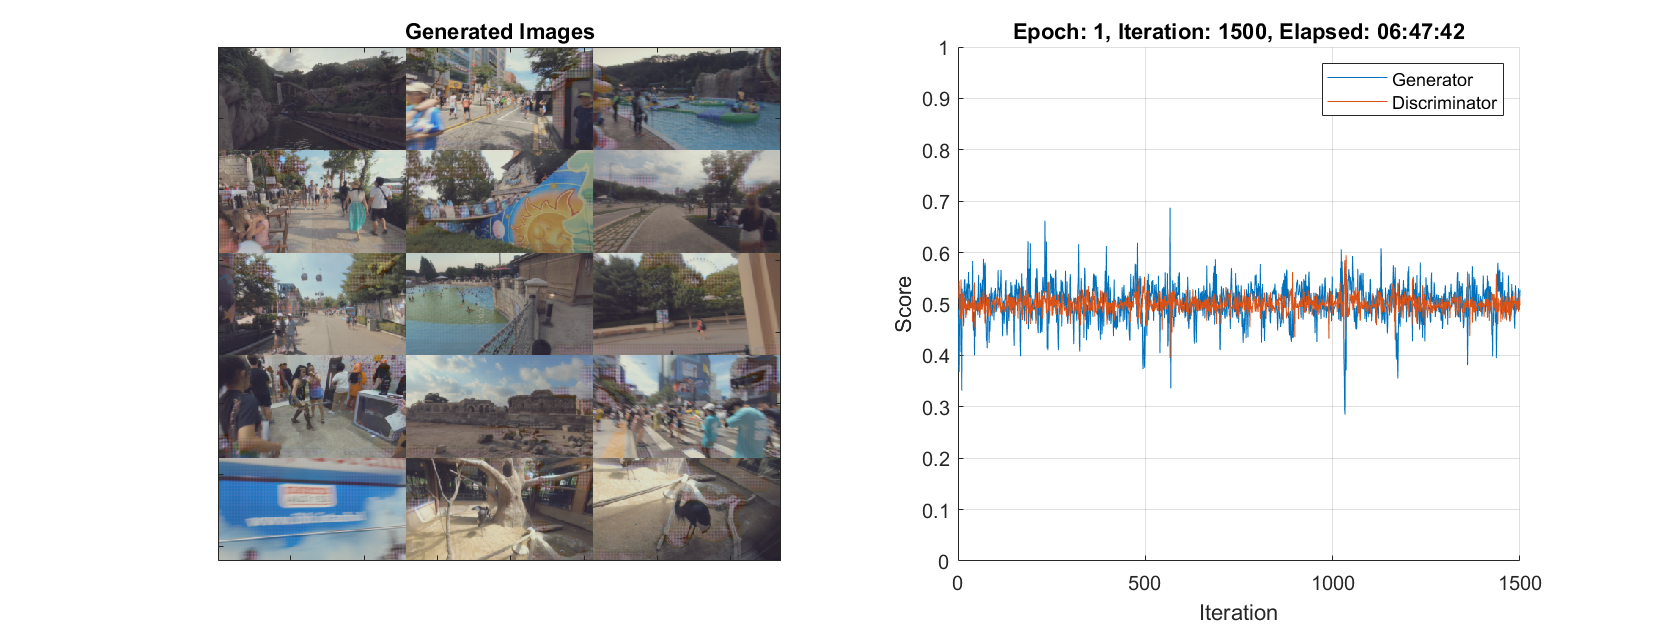

trailingAvgGenerator = [];
trailingAvgSqGenerator = [];
trailingAvgDiscriminator = [];
trailingAvgSqDiscriminator = [];
executionEnvironment = 'auto';
numValidationImages = 16;
f = figure;
f.Position(3) = 2*f.Position(3);
imageAxes = subplot(1,2,1);
scoreAxes = subplot(1,2,2);
lineScoreGenerator = animatedline(scoreAxes,'Color',[0 0.447 0.741]);
lineScoreDiscriminator = animatedline(scoreAxes, 'Color', [0.85 0.325 0.098]);
legend('Generator','Discriminator');
ylim([0 1])
xlabel("Iteration")
ylabel("Score")
grid on
iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs
    
    % Reset and shuffle datastore.
    reset(trainTrue);
    reset(trainBlur);
    trainBlur = shuffle(trainBlur);
    trainTrue = shuffle(trainTrue);
    
    % Loop over mini-batches.
    while hasdata(trainTrue)
        iteration = iteration + 1;
        
        % Read mini-batch of data.
        data = read(trainTrue);
        %size(data)
        noisyData = read(trainBlur);
        %size(noisyData)
        
        % Ignore last partial mini-batch of epoch.
        if size(data,1) < miniBatchSize
            continue
        end
        
        % Concatenate mini-batch of data and generate latent inputs for the
        % generator network.
        X = cat(4,data{:,1}{:});
        X = single(X);
        Z = cat(4,noisyData{:,1}{:});
        Z = single(Z);
        
        % Rescale the images in the range [-1 1].
        X = rescale(X,-1,1,'InputMin',0,'InputMax',255);
        Z = rescale(Z,-1,1,'InputMin',0,'InputMax',255);
        
        % Convert mini-batch of data to dlarray and specify the dimension labels
        % 'SSCB' (spatial, spatial, channel, batch).
        dlX = dlarray(X, 'SSCB');
        dlZ = dlarray(Z, 'SSCB');
        
        % If training on a GPU, then convert data to gpuArray.
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlX = gpuArray(dlX);
            dlZ = gpuArray(dlZ);
        end
        
        % Evaluate the model gradients and the generator state using
        % dlfeval and the modelGradients function listed at the end of the
        % example.
        [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator] = ...
            dlfeval(@modelGradients, dlnetGenerator, dlnetDiscriminator, dlX, dlZ, flipFactor);
        dlnetGenerator.State = stateGenerator;
        
        % Update the discriminator network parameters.
        [dlnetDiscriminator,trailingAvgDiscriminator,trailingAvgSqDiscriminator] = ...
            adamupdate(dlnetDiscriminator, gradientsDiscriminator, ...
            trailingAvgDiscriminator, trailingAvgSqDiscriminator, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
        
        % Update the generator network parameters.
        [dlnetGenerator,trailingAvgGenerator,trailingAvgSqGenerator] = ...
            adamupdate(dlnetGenerator, gradientsGenerator, ...
            trailingAvgGenerator, trailingAvgSqGenerator, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
        
        % Every validationFrequency iterations, display batch of generated images using the
        % held-out generator input
        if mod(iteration,validationFrequency) == 0 || iteration == 1
            % Generate images using the held-out generator input.
            dlXGeneratedValidation = predict(dlnetGenerator,dlZ);
            
            % Tile and rescale the images in the range [0 1].
            list = extractdata(dlXGeneratedValidation);
            I = imtile(list(:,:,:,1:15));
            I = rescale(I);
            
            % Display the images.
            subplot(1,2,1);
            image(imageAxes,I)
            xticklabels([]);
            yticklabels([]);
            title("Generated Images");
        end
        
        % Update the scores plot
        subplot(1,2,2)
        addpoints(lineScoreGenerator,iteration,...
            double(gather(extractdata(scoreGenerator))));
        
        addpoints(lineScoreDiscriminator,iteration,...
            double(gather(extractdata(scoreDiscriminator))));
        
        % Update the title with training progress information.
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        title(...
            "Epoch: " + epoch + ", " + ...
            "Iteration: " + iteration + ", " + ...
            "Elapsed: " + string(D))
        
        drawnow
    end
end

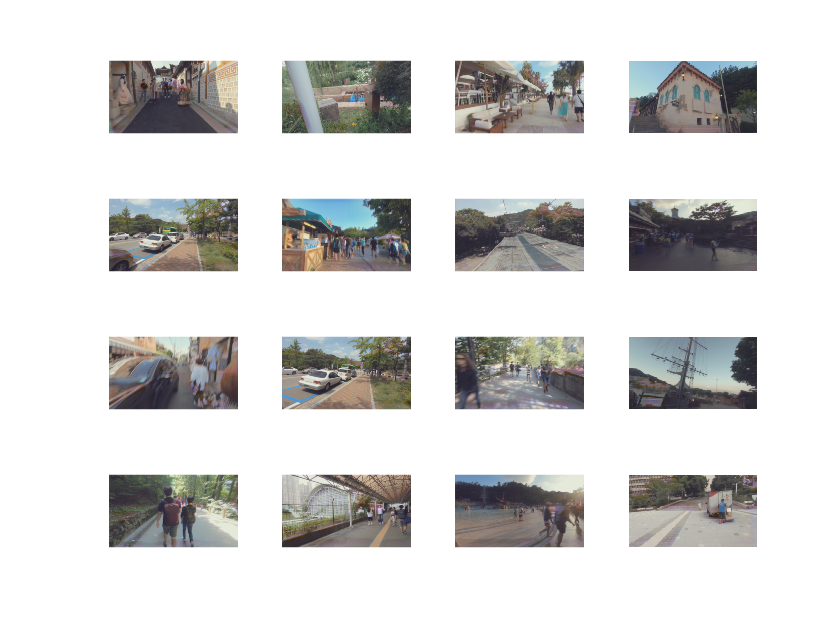

reset(trainBlur);
shuffle(trainBlur);
noisyData = trainBlur.read();
Z = cat(4,noisyData{:,1}{:});
Z = single(Z);
Z = rescale(Z,-1,1,'InputMin',0,'InputMax',255);
list = dlarray(Z,'SSCB');
denoiseList = extractdata(predict(dlnetGenerator,list));
denoiseList = rescale(denoiseList);
figure;
subplot(4,4,1);
for k = 1:16
    subplot(4,4,k);
    imshow(denoiseList(:,:,:,k));
end

save('ganAgents.mat','dlnetGenerator', 'dlnetDiscriminator')

function [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator] = ...
    modelGradients(dlnetGenerator, dlnetDiscriminator, dlX, dlZ, flipFactor)

% Calculate the predictions for real data with the discriminator network.
dlYPred = forward(dlnetDiscriminator, dlX);

% Calculate the predictions for generated data with the discriminator network.
[dlXGenerated,stateGenerator] = forward(dlnetGenerator,dlZ);
dlYPredGenerated = forward(dlnetDiscriminator, dlXGenerated);

% Convert the discriminator outputs to probabilities.
probGenerated = sigmoid(dlYPredGenerated);
probReal = sigmoid(dlYPred);

mean(probReal);
mean(1-probGenerated);

% Calculate the score of the discriminator.
scoreDiscriminator = ((mean(probReal)+mean(1-probGenerated))/2);

% Calculate the score of the generator.
scoreGenerator = mean(probGenerated);

% Randomly flip a fraction of the labels of the real images.
numObservations = size(probReal,4);
idx = randperm(numObservations,floor(flipFactor * numObservations));

% Flip the labels
probReal(:,:,:,idx) = 1-probReal(:,:,:,idx);

% Calculate the GAN loss.
[lossGenerator, lossDiscriminator] = ganLoss(probReal,probGenerated);

% For each network, calculate the gradients with respect to the loss.
gradientsGenerator = dlgradient(lossGenerator, dlnetGenerator.Learnables,'RetainData',true);
gradientsDiscriminator = dlgradient(lossDiscriminator, dlnetDiscriminator.Learnables);

end

function [lossGenerator, lossDiscriminator] = ganLoss(probReal,probGenerated)

probReal = max(probReal, .00001);
probGenerated = max(.00001, min(probGenerated, .99999));

% Calculate the loss for the discriminator network.
lossDiscriminator =  -mean(log(probReal)) -mean(log(1-probGenerated));

% Calculate the loss for the generator network.
lossGenerator = -mean(log(probGenerated));

end